# AOI_Lab : BardcodeRead

#### Fred liu 2023.07.12

使用readBarcode的指令可以辨識一維與二維的條碼

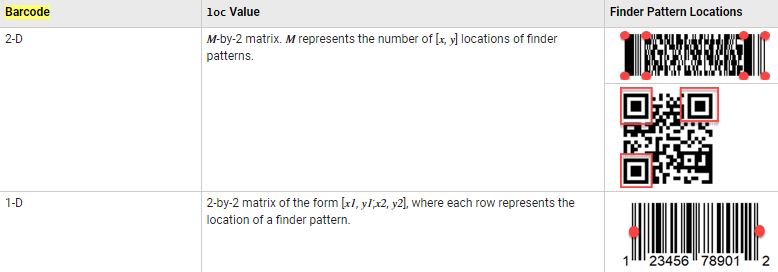

#### 參數設定 : `format`** — Barcode format**

`'all'` — Use this option to specify all valid barcode formats. If you do not specify a format, the function uses this option.

`'1D'` — Use this option to specify all valid 1-D barcode formats.

`'2D'` — Use this option to specify all valid 2-D barcode formats

#### 支援的Bacode格式

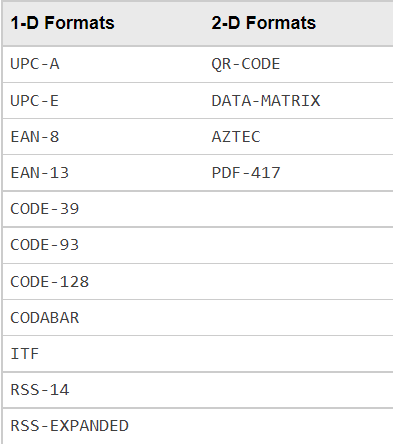

### **二維條碼測試(Read a QR Barcode)**

I = imread("code04.jpg");
[msg, ~, loc] = readBarcode(I);

% Annotate the image with the decoded message.
xyText =  loc(1,:);
Imsg = insertText(I, xyText, msg, "BoxOpacity", 1, "FontSize", 25);
disp(msg)

https://medium.com/@FredLiu_


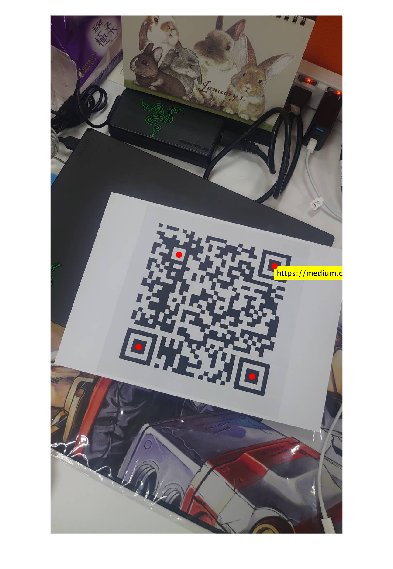

% Insert filled circles at the finder pattern locations.
Imsg = insertShape(Imsg, "FilledCircle", [loc, ...
    repmat(10, length(loc), 1)], "Color", "red", "Opacity", 1);

% Display image.
imshow(Imsg)

### `一維條碼測試(`**Search Image for 1-D Barcode**`)`

I = imread("barcode1D.jpg");
msg = readBarcode(I);
disp("Decoded barcode message: " + msg)

Decoded barcode message: 1234567890128


I = imread("barcode1D.jpg");
[msg,detectedFormat,loc] = readBarcode(I,'1D');
disp("Barcode format: " + detectedFormat)

Barcode format: EAN-13


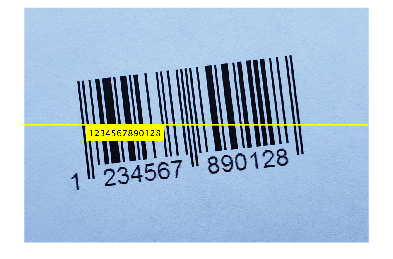


xyBegin = loc(1,:);
Imsg = insertText(I,xyBegin,msg,'BoxOpacity',1,'FontSize',30);

imSize = size(Imsg);
Imsg = insertShape(Imsg,'Line',[1 xyBegin(2) imSize(2) xyBegin(2)],'LineWidth',5);

figure,imshow(Imsg)

**(Improving Barcode Detection)**

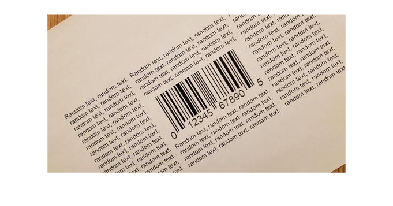

I = imread("rotated1DBarcode.jpg");
figure,imshow(I)

readBarcode(I)

ans = ""

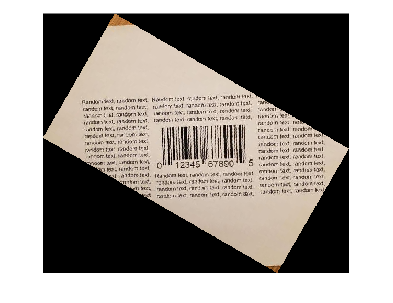

Irot = imrotate(I, -30);
figure,imshow(Irot)

readBarcode(Irot)

ans = "012345678905"